# Portrait segmentation using DeepLab V3 and Resnet-18

**Based on link below**

[https://www.mathworks.com/help/vision/ug/semantic-segmentation-using-deep-learning.html](https://www.mathworks.com/help/vision/ug/semantic-segmentation-using-deep-learning.html) 

**Download dataset below, extract into same folder as Matlab to train it**

[https://www.dropbox.com/s/bv8r5vmjc52a8s6/supervisely_portrait.zip](https://www.dropbox.com/s/bv8r5vmjc52a8s6/supervisely_portrait.zip) 

**Download the pre-trained model if you dont wanna train it yourself**

https://drive.google.com/file/d/148b9CvT5GWWjVDeMTvXHUjX4cIF36_Y0/view?usp=sharing

**Section 1.**

**If you wanna train the dataset yourself, run section below**

imageDir = fullfile('.\','images/'); % Load portraits
labelDir = fullfile('.\', 'masks/'); % Ladataan portrait masks

Create an `imageDatastore` object to store the training images.

imds = imageDatastore(imageDir, 'ReadFcn', @customDataReader); % Save images, transform into 512x512x3 images
cmap = [
    255 255 255   % Tausta
    0 0 0 % Henkilö
    ];
cmap = cmap ./ 255; % Normalize

Define the class names and their associated label IDs.

classNames = [ "person"
    "background"]; % Define class name

labelIDs = personPixelLabelIDs(); % Label pixel IDs


Create a `pixelLabelDatastore` object to store the ground truth pixel labels for the training images.

pxds = pixelLabelDatastore(labelDir,classNames,labelIDs, 'ReadFcn', @customDataReader); % Save masks (pixel data) and transform  masks into 512x512x3 images

Create the U-Net network.

imageSize = [512 512 3]; % Define input image size
numClasses = 2; % Person/Background segmentation
network = 'resnet18'; % Define network
lgraph = deeplabv3plusLayers(imageSize,numClasses,network, ... % Use deeplab v3 on top of resnet-18
             'DownsamplingFactor',16);

Create a datastore for training the network.

augmenter = imageDataAugmenter('RandXReflection',true,...
    'RandXTranslation',[-10 10],'RandYTranslation',[-10 10]); % Augment images randomly so we get to train on different angles etc..
ds = pixelLabelImageDatastore(imds,pxds,'OutputSize',[512 512 2], 'DataAugmentation',augmenter); 

Set training options.

options = trainingOptions('sgdm', ... % Stochastic Gradient Descent
    'LearnRateSchedule','piecewise',... % Algorithm to change learning rate
    'LearnRateDropPeriod',10,... % After how many epochs we drop learning rate -> does nothing in this case as max epoch is 10
    'LearnRateDropFactor',0.3,... % How much we drop the learning rate
    'Momentum',0.9, ... % Moving average of data factor
    'InitialLearnRate',1e-3, ... % Initial learn rate
    'L2Regularization',0.005, ... % Ridge regression
    'ExecutionEnvironment','gpu', ... % Use gpu to train
    'MaxEpochs',10, ...   % 10 epochs
    'MiniBatchSize',8, ... % use 8 data points before calculating gradient
    'Shuffle','every-epoch', ... % Shuffle data after every epoch
    'CheckpointPath', tempdir, ... % Save data to tempdir
    'VerboseFrequency',20,... % Print every 20 iterations
    'Plots','training-progress'); % Plot training progress in seperate window

**Section 2. Train the network or skip the training if you use pretrained network**

if isfile('seg10epoch.mat') % If we have already trained the dataset, use it
    load('seg10epoch.mat')
else
    d3net = trainNetwork(ds,lgraph,options); % else train using above options
end

**Section 3.** **Segment images**

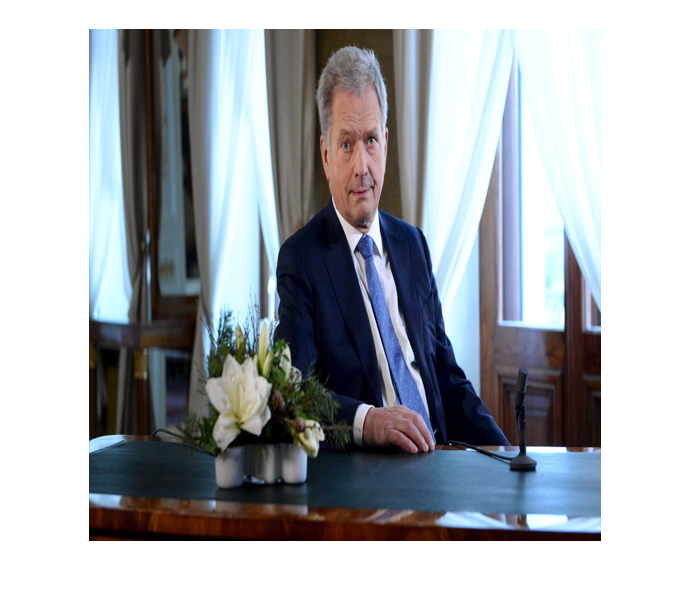

I = imread('pics\sale.jpg'); % Load foreground image
I = imresize(I, [512 512]); % Resize to fit our network
background = imread('pics\fire.jpg'); % Load background iamge
imshow(I) % Show original image

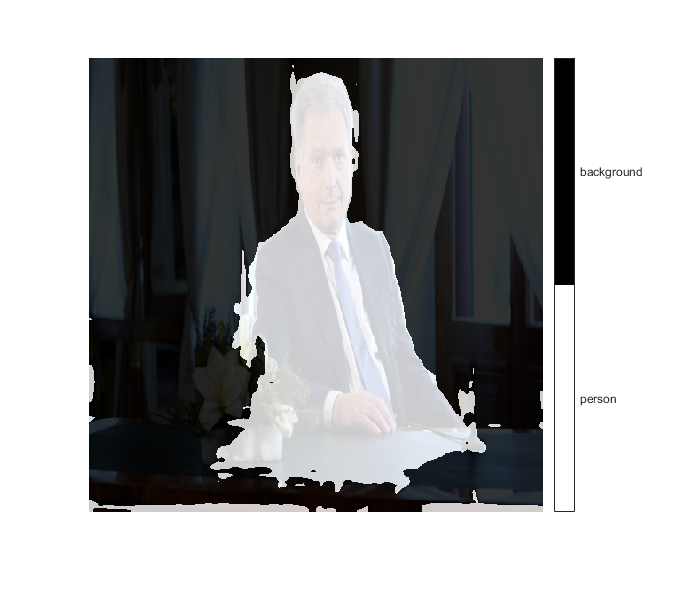

C = semanticseg(I, d3net); % Do semantic segmentation using our neural network
B = labeloverlay(I,C,'Colormap',cmap,'Transparency',0.2); % Map segmentation above original image
imshow(B) % Display segmentation map
pixelLabelColorbar(cmap, classNames); % Display labels for pixel colors    

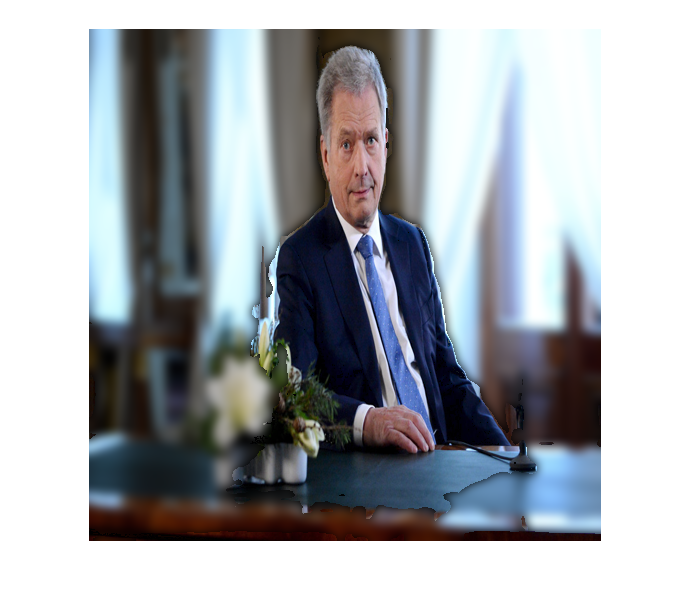

%imshow(changeBackground(I,background, C)) % Change background of image
imshow(blurImage(I, C)) % Blur image background
hold off

**Section 4. Segment webcam**

h = figure;
cam = webcam() % Define webcam

cam =   webcam with properties:

                     Name: 'Logitech HD Webcam C525'
     AvailableResolutions: {1×22 cell}
               Resolution: '640x480'
                Sharpness: 22
             ExposureMode: 'auto'
                    Focus: 70
               Brightness: 150
             WhiteBalance: 3699
                     Gain: 102
    BacklightCompensation: 1
                     Tilt: 0
               Saturation: 32
                     Zoom: 1
                      Pan: 0
                 Exposure: -5
                 Contrast: 32


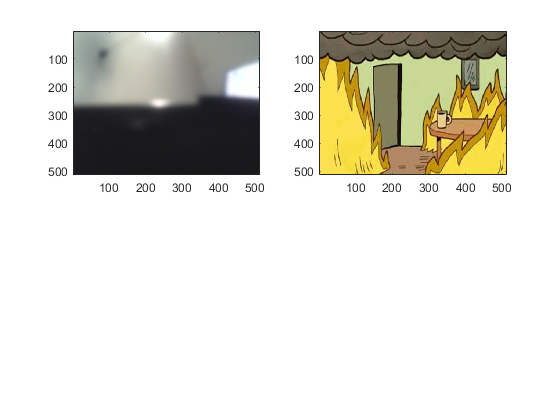

cam.Brightness = 150;
while ishandle(h)
    im = snapshot(cam); % Take image
    resized = imresize(im, [512 512]); % Resize camera image
    C = semanticseg(resized, d3net); % Segment
    B = labeloverlay(resized,C,'Colormap',cmap,'Transparency',0.2); % Overlay
    subplot(2,2,1); % Plot both
    image(blurImage(resized, C))
    subplot(2,2,2);
    image(changeBackground(resized, background, C))
end 

hold off